rng(10);
taxi_data = cvpartition(H.fault,"HoldOut",0.2)

taxi_data = Hold-out cross validation partition
   NumObservations: 52518
       NumTestSets: 1
         TrainSize: 42015
          TestSize: 10503

taxiTest = H(taxi_data.test,:)

taxiTest = 10503×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperature__

taxiTrain = H(taxi_data.training,:)

taxiTrain = 42015×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperature_

[modelStruct, validationAccuracy] = trainClassifier(taxiTrain)

modelStruct = struct with fields:
                     predictFcn: @(x)neuralNetworkPredictFcn(predictorExtractionFcn(x))
              RequiredVariables: {1×28 cell}
    ClassificationNeuralNetwork: [1×1 ClassificationNeuralNetwork]
                          About: 'This struct is a trained model exported from Classification Learner R2021a.'
                   HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy = 0.9960

myModel = modelStruct.ClassificationNeuralNetwork

myModel =   ClassificationNeuralNetwork
           PredictorNames: {1×28 cell}
             ResponseName: 'Y'
    CategoricalPredictors: 28
               ClassNames: [1×24 categorical]
           ScoreTransform: 'none'
          NumObservations: 41886
               LayerSizes: 100
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [349×7 table]


  Properties, Methods



yActual = taxiTest.fault;
yPredicted = modelStruct.predictFcn(taxiTest);
%residuals = yActual - yPredicted;
%testMetrics = rMetrics(yActual, yPredicted)

%scatter(yActual, yPredicted, ".")
%probplot('normal',yActual);figure(gcf)

%xlabel("Actual value")
%ylabel("Predicted Value")
%title("results from training and testing")

%histogram2(yActual, yPredicted, 100, "DisplayStyle","tile")
%line([0 120], [0 0], "Color", "k")
%xlabel("Actual Response")
%ylabel("Residuals")
%title("Residuals Plot")
%cb = colorbar();
%cb.Label.String = "No. of Data Points";

taxiTrain2021 = taxiTrain

taxiTrain2021 = 42015×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperat

taxiTrain2021.Time = taxiTrain.Time + years(2.2) 

taxiTrain2021 = 42015×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperat


taxiTrain2021.fault = taxiTrain.fault

taxiTrain2021 = 42015×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperat

taxiTrain2021 = providedPreprocessinggg(taxiTrain2021) 

taxiTrain2021 = 42015×34 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperat

% Display only the first 8 rows of the table
head(taxiTrain2021,8)

ans = 8×34 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperature__real_valu

intervalStartTime1 = '29-May-2021';
intervalEndTime1 = '15-October-2021';
idx1 = isbetween(taxiTrain2021.Time,intervalStartTime1,intervalEndTime1);
taxiTrain2021 = taxiTrain2021(idx1,:); %Stores only the rows with the desired time instances

taxiTest2021 = taxiTest

taxiTest2021 = 10503×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperatu

taxiTest2021.Time = taxiTest.Time + years(2.2) 

taxiTest2021 = 10503×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperatu




taxiTest2021.fault = taxiTest.fault

taxiTest2021 = 10503×30 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperatu

taxiTest2021 = providedPreprocessinggg(taxiTest2021) 

taxiTest2021 = 10503×34 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperatu

% Display only the first 8 rows of the table
head(taxiTest2021,8)

ans = 8×34 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperature__real_valu

%Here, the 'time' column in the 'data' table stores the complete time for that instance
%in the format 'dd-MMM-yyyy hh:mm:ss'.
intervalStartTime2 = '29-May-2021';
intervalEndTime2 = '15-October-2021';
idx2 = isbetween(taxiTest2021.Time,intervalStartTime2,intervalEndTime2);
taxiTest2021 = taxiTest2021(idx2,:); %Stores only the rows with the desired time instances
head(taxiTest2021,8)

ans = 8×34 table
            Time            signal__required_value__fan_exahust_air    logic__real_value__filter_exahust_air    logic__real_value__fan_fresh_air    logic__real_value__air_handling_unit    signal__required_value__heater_valve    water_temperature__required_value__heater    air_temperature__required_value__exahust_air_inlet    signal__min__fan_fresh_air    logic__required_value__valve_exahust_air_outlet    air_temperature__max__supply_air_outlet    logic__real_value__filter_outdoor_air    logic__required_value__valve_outdoor_air    water_temperature__real_value__heater_behind    air_temperature__real_value__exahust_air_inlet    air_temperature__min__supply_air_outlet    air_temperature__real_valu

%myDay = datetime("2022-02-28")
%taxiTrain = taxiTrain2021(day(taxiTrain2021.Time,"dayofyear") == day(myDay,"dayofyear"),:)

%taxiTrain2021.signal__max__fan_fresh_air = modelStruct.predictFcn(taxiTrain)

%taxiTest2021.signal__max__fan_fresh_air = modelStruct.predictFcn(taxiTest)

%taxiPickupsMyDayTotals = groupsummary(taxiTrain,"fault","sum","signal__max__fan_fresh_air");
%taxiPickupsMyDay = join(taxiTrain,taxiPickupsMyDayTotals,"RightVariables","sum_signal__max__fan_fresh_air")
%taxiPickupsMyDay.PickupFraction = taxiPickupsMyDay.signal__max__fan_fresh_air./taxiPickupsMyDay.sum_signal__max__fan_fresh_air
%taxiPickupsMyDayFractions = unstack(taxiPickupsMyDay,"PickupFraction","fault","GroupingVariables","sum_signal__max__fan_fresh_air")

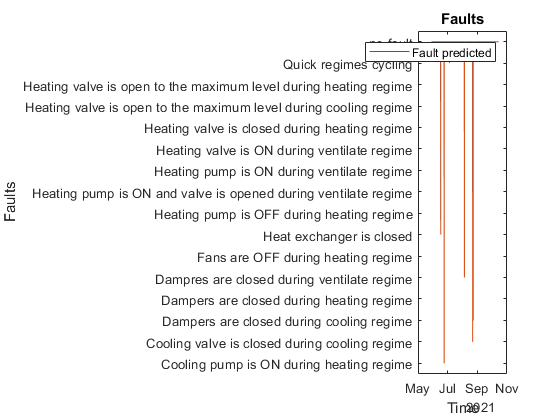

plot(taxiTrain2021.Time,taxiTrain2021.fault)
%xlim([datetime(2022,02,28,17,27,36)...
 %datetime(2022,02,28,19,47,36)])

%xlim([21.379 22.487])
%ylim([0.0 71.4])
%ylim([0.00 1])
legend({'Fault actual'})
title('Faults')
xlabel('Time')
ylabel('Faults')



hold on

plot(taxiTest2021.Time,taxiTest2021.fault)
%xlim([datetime(2022,02,28,17,27,36)...
 %datetime(2022,02,28,19,47,36)])

%xlim([21.379 22.487])
%ylim([0.0 71.4])
%ylim([0.00 1])
legend({'Fault predicted'})
title('Faults')
xlabel('Time')
ylabel('Faults')

YAct = taxiTest2021.fault

YAct = 8022×1 categorical array
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 


Ypred = modelStruct.predictFcn(taxiTest2021)

Ypred = 8022×1 categorical array
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 
     no fault 


Confusion = confusionmat(YAct,Ypred)

Confusion =      7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     5     0     0     0     0     0     0     0     0     4     0     0     0    

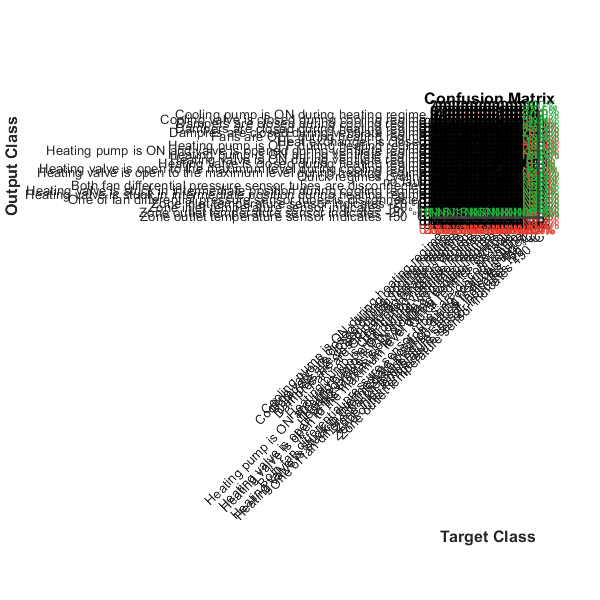

plotconfusion(YAct,Ypred)

ConfusionT = Confusion';
diagonal = diag(ConfusionT);
sum_of_raws = sum(ConfusionT,2);
precision = diagonal ./ sum_of_raws

precision =     1.0000
    0.8750
    0.8000
       NaN
    0.8000
       NaN
    0.7143
       NaN
    1.0000
    1.0000


Overall_precision = mean(precision)

Overall_precision = NaN


sum_of_columns = sum(ConfusionT,1);
Recall = diagonal ./ sum_of_columns'

Recall =     1.0000
    1.0000
    0.8000
       NaN
    1.0000
       NaN
    0.5556
       NaN
    1.0000
    1.0000


Overall_recall = mean(Recall)

Overall_recall = NaN


f1_score = 2*((Overall_precision*Overall_recall)/(Overall_precision+Overall_recall))

f1_score = NaN


Accuracy = diagonal./(sum_of_raws)

Accuracy =     1.0000
    0.8750
    0.8000
       NaN
    0.8000
       NaN
    0.7143
       NaN
    1.0000
    1.0000


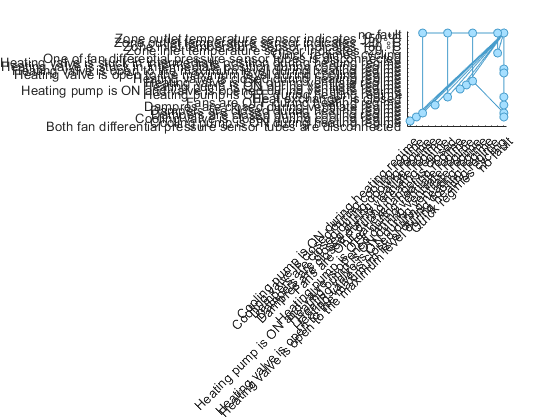

Not enough input arguments.

Error in minimumerror (line 28)
line(XData1,YData2,'DisplayName','Observed min classification error',...



minimumerror(YAct,Ypred)